# Authors: Marta Barriendos & Ana Garcia Armada, Univesidad Carlos III de Madrid

# The envelope characteristics of OFDM and PAPR reduction. Fundamentals of SC-FDMA.

## Introduction

Orthogonal Frequency Division Multiplexing (OFDM) is widely used in modern communication systems due to its robustness against multipath fading and efficient spectral usage. However, one of its main drawbacks is a **high Peak-to-Average Power Ratio (PAPR)**, which requires expensive and power-inefficient RF components.

To address this, **Single Carrier Frequency Division Multiple Access (SC-FDMA)** was introduced, especially in uplink transmissions of LTE systems, offering lower PAPR characteristics.

## Index

- Definition and implementation scheme of SC-FDMA.

- Comparision with OFDM

- SC-FDMA implementation vs OFDM

- PAPR reduction techniques

## 1. Definition and implementation scheme of SC-FDMA

**Single-carrier FDMA** (**SC-FDMA**) is a frequency-division multiple access scheme that deals with the assignment of multiple users to a shared communication resource. 

SC-FDMA can be interpreted as a linearly precoded OFDMA scheme, sice it has an additional DFT processing step preceding the conventional OFDMA processing to reduce the peaks, as we can see in the implementation scheme presented below. 

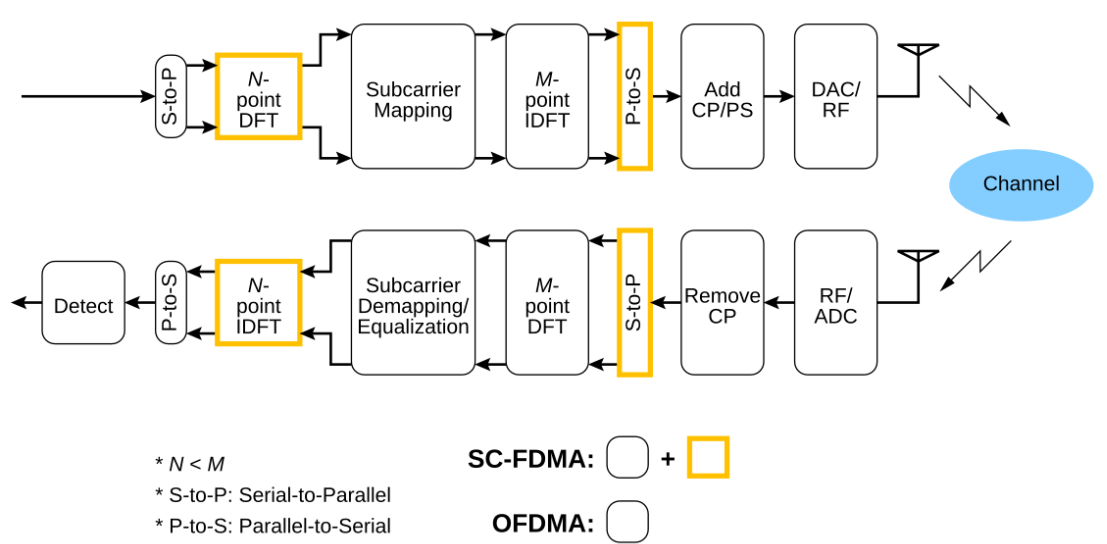

(Acceso múltiple por división de frecuencia de portadora única, *Wikipedia*)

## 2. Comparision with OFDM

SC-FDMA is an attractive alternative to OFDMA, especially in the **uplink communications** where **lower** peak-to-average power ratio (**PAPR**)  greatly **benefits **the **mobile terminal** in terms of transmitting power efficiency and reduced cost of the power amplifier. This is where SC-FDMA gets its name from. it’s an OFDM signal that behaves like a single-carrier QAM signal. Therefore,  the main distinguishing feature of SC-FDMA is that it leads to a **single-carrier transmission signal**, in contrast to OFDMA which is a multi-carrier transmission scheme. 

The fact that in SC-FDMA the transmission signal has a lower peak to average power ratio (PAPR) is a prominent advantage over OFDM and OFDMA, which results in **relaxed design parameters** in the tranmission path. Intuitively, the reason lies in the fact that where OFDM transmit symbols directly modulate multiple sub-carriers, while SC-FDMA transmitted symbols are first processed by an N-point DFT block.

Therefore, in order to reduce the PAPR measure of an OFDM signal, the first approach is to implement it as a SC-FDMA signal, instead of an OFDM signal. This is used specially in the uplink, as we have explained before, for the case of LTE is mandatory, since the problem of a high PAPR value is worst in the uplink, due to the user terminal limitations. However, for the 5G standard, it's possible to use in the uplink both, SC-FDM or OFDM.

Now, we are going to start with the first approach, the SC-FDMA implementation, and later we'll talk about the PAPR reduction techniques for the OFDM signal.

## 3. SC-FDMA implementation and comparison with OFDM

Now, we are going to implement a code that simulates the generation of SC-FDMA signals through QPSK modulation, followed by FFT spreading, IFFT for time-domain conversion, and adding a guard interval. We will also calculate the power metrics and the PAPR for each symbol and visualize the transmitted signal's power spectrum and real part. While generating this SC-FDMA signal, we're going to generate at the same time the original OFDM signal, to verify how this second signal has a PAPR a lot higher than the first one.

We start by defining the different parameters that we are going to use to make this implementation. 

Firstly, we define the total number of samples to simulate ***n_samples*** and the number of subcarriers in the OFDM system ***N_OFDM***, where ***M*** represents the number of symbols to spread. Since this value of ***M*** is going to directly affect to the width of the spectrum, we are going to define two extreme values, one bigger (*12*40*) and another lower (*12*5*). Then, we define the guard interval length ***Ng***, which is 1/8 of the total number of OFDM subcarriers. Finally, the number of OFDM symbols that can be simulated based on the total number of samples is ***N_symb,*** and ***n_samples*** is a variable that will be updated to reflect the actual number of samples after considering the number of symbols.

n_samples=1e6; 
N_OFDM=2048; 
M_high=12*40; 
M_low=12*5; 
Ng=1/8*N_OFDM; 
N_symb=floor(n_samples/N_OFDM); 
n_samples=N_symb.*N_OFDM; 

Once we have defined our parameters, the next step is to initialize an array of zeros to hold the final signal  Its size accounts for all the symbols, including the guard interval for each.

signal=zeros(1,N_symb*(N_OFDM+Ng));
signal_scfdma_highM=zeros(1,N_symb*(N_OFDM+Ng));
signal_scfdma_lowM=zeros(1,N_symb*(N_OFDM+Ng));

The next step is to implement the transmission loop, that runs for each OFDM symbol (from 1 to N_symb). Initializes for each symbol the parameters: ***ini, ***that is a starting index for spreading the signal (arbitrary set to 500), and ***spread_ord, ***that is an array initialized to hold the spread symbols.

Then we generate the symbol using a QPSK modulation, and obtaining the signal "***qpsk***", after which we spread the symbols applying the Fast Fourier Transform (FFT) to the QPSK symbols, to spread them over M subcarriers. As we are going to see later, this value will affect to the width of bandwidth of the spectrum.The spread symbols are stored in the ***spread_ord*** array, starting from index ***ini***. The next step is to do the Inverse FFT for SC-FDMA, ***scfdma1***, to convert the symbols back to the time domain, producing the SC-FDMA signal. Next, we add the guard interval to the signal, for doing this, the last **Ng** samples of the IFFT output are prepended to the beginning of the signal.

Finally, the SC-FDMA signal for the current symbol, including the guard interval, is stored in the ***signal*** array, and we calculate the power and PAPR, using the following metrics:

- ***mean_p***: Mean power of the current symbol.

- ***max_p***: Maximum power of the current symbol.

- ***papr***: Peak-to-Average Power Ratio calculated for each symbol ->   $\textrm{PAPR}=\frac{\max_p }{{\textrm{mean}}_p }$

In the next code, before calculating the SC-FDMA signal explained before, we start calculating the original OFDM signal to see the PAPR reduction obtained by the implementation of a SC-FDMA.

%Initializing the signals for the PAPR value of the original OFDM signal,
%and for the SC-FDMA (with reduced PAPR)
papr_ofdm = zeros(1, N_symb);
papr_scfdma = zeros(1, N_symb);

for symb = 1:N_symb

    % 1. Generating the QPSK symbols
    i = sign(rand(1, M_high) - 0.5);
    q = sign(rand(1, M_high) - 0.5);
    qpsk = i + 1j * q;

    % ===== Basic OFDM Signal =====
    
    % Assigning the QPSK symbols to the subcarriers.
    ofdm_symbols = zeros(1, N_OFDM);
    ofdm_symbols(1:M_high) = qpsk;  % Placing the QPSK symbols in the first M_high subcarriers, it's a basic OFDM without spreading

    % FFT to be in the time domain. 
    ofdm_time = ifft(ofdm_symbols, N_OFDM);

    % Adding the guard interval (Cyclic Prefix)
    ofdm_cp = [ofdm_time(N_OFDM - Ng + 1 : N_OFDM), ofdm_time];
    
    %Save the OFDM symbol
    signal(1, (symb - 1) * (N_OFDM + Ng) + 1 : symb * (N_OFDM + Ng)) = ofdm_cp;

    % Calculating the PAPR of the symbol for the OFDM signal.
    mean_power_ofdm = mean(abs(ofdm_cp).^2);
    max_power_ofdm = max(abs(ofdm_cp).^2);
    papr_ofdm(symb) = max_power_ofdm / mean_power_ofdm;

    % ===== SC-FDMA Signal (Reduced PAPR) =====
    ini=500;

    i_low = sign(rand(1, M_low) - 0.5);
    q_low = sign(rand(1, M_low) - 0.5);
    qpsk_low = i_low + 1j * q_low;

    % Spreading of the QPSK symbols using the FFT.
    spread_high = fft(qpsk, M_high);
    spread_low = fft(qpsk, M_low);
    
    % Placing the spread symbols
    spread_ord_high = zeros(1, N_OFDM);
    spread_ord_low = zeros(1, N_OFDM);

    spread_ord_high(1,ini:ini+M_high-1)=spread_high;
    spread_ord_low(1,ini:ini+M_low-1)=spread_low;

    % IFFT to obtain the SC-FDMA in the time domain.
    scfdma_time_high = ifft(spread_ord_high, N_OFDM);
    scfdma_time_low = ifft(spread_ord_low, N_OFDM);

    % Adding the guard interval (Cyclic Prefix)
    scfdma_cp_high = [scfdma_time_high(N_OFDM - Ng + 1 : N_OFDM), scfdma_time_high];
    scfdma_cp_low = [scfdma_time_low(N_OFDM - Ng + 1 : N_OFDM), scfdma_time_low];

    %Saving the signals

    signal_scfdma_highM(1, (symb - 1) * (N_OFDM + Ng) + 1 : symb * (N_OFDM + Ng)) = scfdma_cp_high;
    signal_scfdma_lowM(1, (symb - 1) * (N_OFDM + Ng) + 1 : symb * (N_OFDM + Ng)) = scfdma_cp_low;

    % Calculating the PAPR for the SC-FDMA signal and higher M
    mean_power_scfdma = mean(abs(scfdma_cp_high).^2);
    max_power_scfdma = max(abs(scfdma_cp_high).^2);
    papr_scfdma(symb) = max_power_scfdma / mean_power_scfdma;

    % Calculating the PAPR for the SC-FDMA signal and lower M
    mean_power_scfdma_low = mean(abs(scfdma_cp_low).^2);
    max_power_scfdma_low = max(abs(scfdma_cp_low).^2);
    papr_scfdma_low(symb) = max_power_scfdma_low / mean_power_scfdma_low;

end

Once we have calculated the PAPR value for each OFDM symbol, and for each SC-FDMA symbol, we can calculate in each case (OFDM and SC-FDMA) the mean value of all the symbols, and with that value obtain the average PAPR in dB.

In the example presented below, the **PAPR** value for the **OFDM** signal is **8.85 dB**, however, if we implement the system with the **SC-FDMA** signal, instead of using the OFDM one, we get a **PAPR** value for the **higher M of 6.30 dB**, and a value of **5.32 dB for the lower M**, which means a r**eduction of the PAPR** value of 2.55 dB and 3.53 dB respectively.

papr_ofdm_mean=mean(papr_ofdm);
papr_scfdma_mean=mean(papr_scfdma);
papr_scfdma_low_mean=mean(papr_scfdma_low);

% Converting the PAPR value to dB
papr_ofdm_dB = 10 * log10(papr_ofdm);
papr_scfdma_dB = 10 * log10(papr_scfdma);
papr_scfdma_low_dB = 10 * log10(papr_scfdma_low);

% Results: Average PAPR of OFDM and SC-FDMA
fprintf('Average PAPR of the OFDM signal: %.2f dB\n', 10*log10(papr_ofdm_mean));

Average PAPR of the OFDM signal: 8.86 dB


fprintf('Average PAPR of the SC-FDMA signal and a higher M: %.2f dB\n', 10*log10(papr_scfdma_mean));

Average PAPR of the SC-FDMA signal and a higher M: 6.20 dB


fprintf('Average PAPR of the SC-FDMA signal and a lower M: %.2f dB\n', 10*log10(papr_scfdma_low_mean));

Average PAPR of the SC-FDMA signal and a lower M: 5.39 dB


Finally, since the reduction of the PAPR value implies a reduction of the peaks of the signal, we can represent the original OFDM signal, compared to the SC-FDMA signal, for the two extreme *M* values, to verify how the SC-FDMA signals have less peaks than the OFDM signal, which clearly reflects the idea of a reduction of the PAPR value.

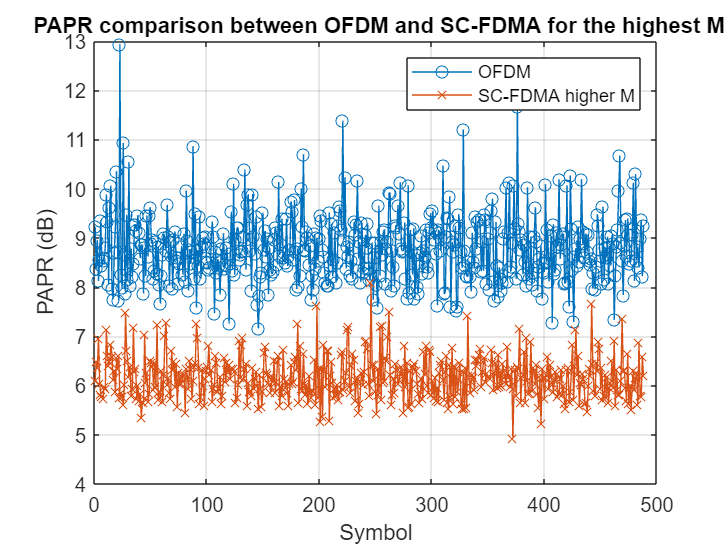

figure;
plot(1:N_symb, papr_ofdm_dB, '-o', 'DisplayName', 'OFDM');
hold on;
plot(1:N_symb, papr_scfdma_dB, '-x', 'DisplayName', 'SC-FDMA higher M');
xlabel('Symbol');
ylabel('PAPR (dB)');
legend;
title(' PAPR comparison between OFDM and SC-FDMA for the highest M');
grid on;

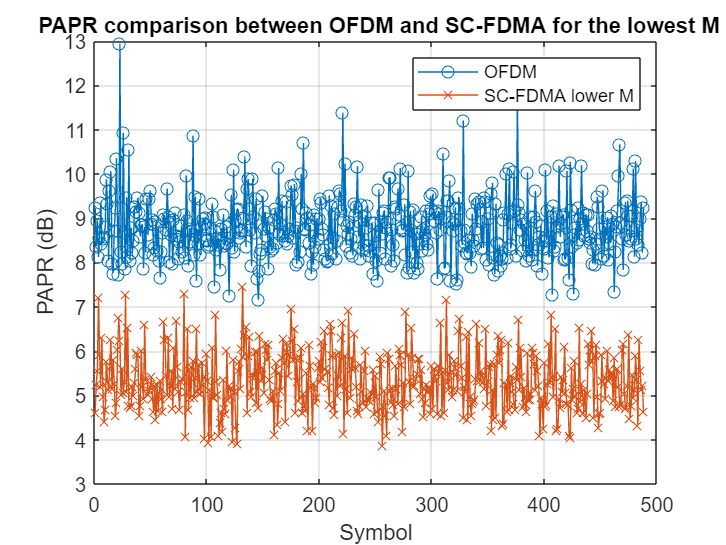

figure;
plot(1:N_symb, papr_ofdm_dB, '-o', 'DisplayName', 'OFDM');
hold on;
plot(1:N_symb, papr_scfdma_low_dB, '-x', 'DisplayName', 'SC-FDMA lower M');
xlabel('Symbol');
ylabel('PAPR (dB)');
legend;
title(' PAPR comparison between OFDM and SC-FDMA for the lowest M');
grid on;

As we were expecting, for both *M* values, the SC-FDMA signal has lower peaks, which results in a lower PAPR.

These graphs are very important, since analyzing the **envelope of the time-domain **signal is crucial for assessing the PAPR. The envelope represents the **instantaneous power of the signal**, and the **peaks** in this plot directly relate to the **maximum power the amplifier must handle**.Therefore, the ratio of the maximum envelope (peak power) to the average power, provides a measure of how extreme the peaks are relative to the average power. A high PAPR can lead to inefficiencies in power amplifiers, which can cause nonlinear distortion if the amplifier is driven into saturation.

Finally, we plot the power spectrum of the transmitted signal (***pspectrum(signal)***) for the three previous cases, the original OFDM signal, the SC-FDMA with the highest *M*, and the SC-FDMA with the lowest *M*. We can verify how for the biggest values of M, the symbols spreading is bigger, and therefore, the width of the spectrum is also bigger, in fact there's a lof of difference between the highest and lowest value of M in the spectrum width, since the last one has less than half of the width of the spectrum for the highest M. 

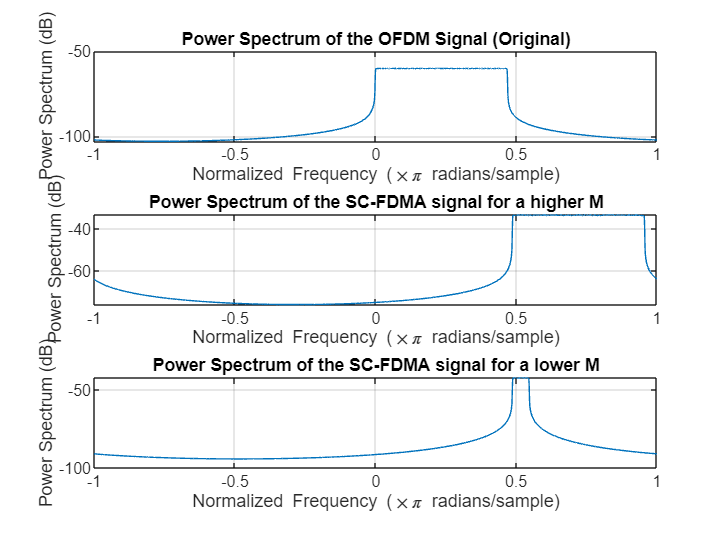

% Power Spectrum of the Original OFDM Signal
figure;
subplot(3,1,1)
pspectrum(signal);
title('Power Spectrum of the OFDM Signal (Original)');
subplot(3,1,2)
pspectrum(signal_scfdma_highM);
title('Power Spectrum of the SC-FDMA signal for a higher M');
subplot(3,1,3)
pspectrum(signal_scfdma_lowM);
title('Power Spectrum of the SC-FDMA signal for a lower M');

With the previous spectrums, we can see how the signal's power is distributed across different frequencies. It shows how power is spread over the available bandwidth, showing a flat profile across the subcarriers.

To finish this section, we have explained that there's **two different approaches to reduce the PAPR value** of an OFDM signal. The first one, that we implemeted before, consists of using a **SC-FDMA implementation**, instead of the corresponding OFDM signal.

However, the second approach is based on the original OFDM signal, to which we apply some P**APR reduction techniques**. This strategy is used in the downlink by the LTE and 5G standards, and it's possible that the 6G standard will also adopt this strategy, however this is unkown right know.

## 4. PAPR reduction techniques

In this section, we want to reduce the peak value of our OFDM signal, in order to reduce the PAPR value, but without damaging the signal. 

There are two main techniques for reducing the peak-to-average power ratio (PAR) in OFDM: Selected Mapping (SLM) and Partial Transmit Sequence (PTS)

- **Selected Mapping (SLM):** This method generates multiple versions of the same OFDM signal, each with a distinct phase shift, to find the version with the lowest peak power. The selected version is transmitted without the need to send side information to the receiver. The decoder can identify the correct phase without side information by analyzing the inherent diversity in the phase shifts, ensuring robust decoding even in noisy channels.

- **Partial Transmit Sequence (PTS):** In PTS, the input data is divided into subblocks, each of which is adjusted in phase to minimize the peak power. Multiple trials of phase combinations are performed, and the configuration with the lowest PAR is selected. Similar to SLM, we can design a decoding method that reconstructs the transmitted phase shifts without requiring side information.

We are going to implement the PAPR reduction technique **SLM**, where we generate several versions of the SC-FDMA signal by applying different random phase sequences and selecting the one with the lowest PAPR value.

U = 2^6;  % Number of SLM sequences(candidates)

% Initializing the results matrices.
signal_original = zeros(1, N_symb * (N_OFDM + Ng));
signal_slm = zeros(1, N_symb * (N_OFDM + Ng));
papr_original = zeros(1, N_symb);
papr_slm = zeros(1, N_symb);

% Generatint the random sequence of phases
phase_sequences = exp(1j *2* pi * randn(U, N_OFDM)); % Random sequences between 0 and 2pi.

for symb = 1:N_symb
    
    % Generating QPSK symbols
    i = sign(rand(1, M_high) - 0.5);
    q = sign(rand(1, M_high) - 0.5);
    qpsk = i + 1j * q;

    % Assigning the QPSK symbols to the first M subcarriers, to get a basic
    % OFDM.
    ofdm_symbols = zeros(1, N_OFDM);
    ofdm_symbols(1:M_high) = qpsk;

    % ===== Original OFDM signal =====
    % IFFT to go to the time domain
    ofdm_time = ifft(ofdm_symbols, N_OFDM);

    % Adding the guard interval (Cyclic Prefix)
    ofdm_cp = [ofdm_time(N_OFDM - Ng + 1 : N_OFDM), ofdm_time];

    % Storing the original OFDM signal.
    signal_original(1, (symb - 1) * (N_OFDM + Ng) + 1 : symb * (N_OFDM + Ng)) = ofdm_cp;

    % Calculating the PAPR value for the original OFDM signal.
    mean_p_original = mean(abs(ofdm_cp).^2);
    max_p_original = max(abs(ofdm_cp).^2);
    papr_original(symb) = max_p_original / mean_p_original;

    % ===== Applying SLM with random phase sequences =====
    papr_candidates = zeros(1, U);
    signals = zeros(U, N_OFDM + Ng);

    for u = 1:U
        % Applying the random phase sequence
        ofdm_symbols_phased = ofdm_symbols .* phase_sequences(u, :);

        % IFFT to get the OFDM signal with SLM.
        ofdm_time_slm = ifft(ofdm_symbols_phased, N_OFDM);

        % Adding the guard interval (Cyclic Prefix)
        ofdm_cp_slm = [ofdm_time_slm(N_OFDM - Ng + 1 : N_OFDM), ofdm_time_slm];

        % Saving each candidate signal
        signals(u, :) = ofdm_cp_slm;

        % Calculating the PAPR value for each SLM sequence
        mean_p_slm = mean(abs(ofdm_cp_slm).^2);
        max_p_slm = max(abs(ofdm_cp_slm).^2);
        papr_candidates(u) = max_p_slm / mean_p_slm;
    end

    % Choosing the signal with the lowest PAPR.
    [~, min_idx] = min(papr_candidates);
    selected_signal = signals(min_idx, :);

    % Storing the SLM signal with the lowest PAPR.
    signal_slm(1, (symb - 1) * (N_OFDM + Ng) + 1 : symb * (N_OFDM + Ng)) = selected_signal;

    % Storing this minimum PAPR value.
    papr_slm(symb) = papr_candidates(min_idx);

end

Once we finish the loop, we'll have for each transmitted symbol, the one with the random phase between 0 and 2$\pi$ that generates the lowest PAPR. Therefore, we can analyze now how much we have reduced the PAPR with this SLM techique. For doing this, we can calculate the average PAPR of all the symbols :

% Calculating the average PAPR and applying the logarithm: 
papr_original_dB = 10 * log10(mean(papr_original));

Average PAPR of the original signal: 8.84 dB


papr_slm_dB = 10 * log10(mean(papr_slm));

Average PAPR of the original signal with SLM: 7.47 dB



% Resulting PAPR of the original OFDM signal, and the signal with a PAPR Reduction (SLM)
fprintf('Average PAPR of the original signal: %.2f dB\n', (papr_original_dB)); 
fprintf('Average PAPR of the original signal with SLM: %.2f dB\n', (papr_slm_dB) ); 

As we can see in the previous analysis, for the original OFDM signal, we get a PAPR value of 8.9 dB, however, if the apply the SLM technique to that original OFDM signal, we get a reduced PAPR of 7.45 dB, which means that thanks to this technique, we can reduce the PAPR value in 1.45 dB. Obviously, with more complex techniques, we could reduce the PAPR value a lot more, but as an example, this perfectly ilustrates that we are able to reduce significantly this value. Moreover, if we represent again the PAPR value for each symbol in dB, it is clear that we are reducing a lot the PAPR of the original OFDM signal.

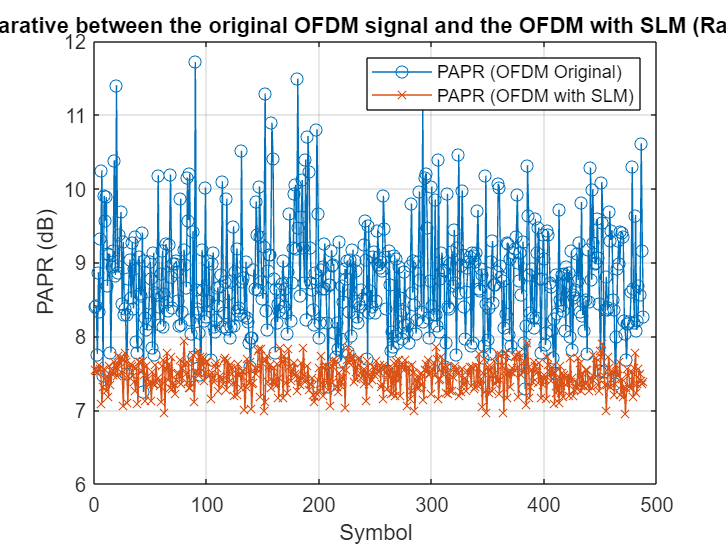

% Comparing the PAPR value of each symbol: 
figure;
plot(1:N_symb, 10 * log10(papr_original), '-o', 'DisplayName', 'PAPR (OFDM Original)');
hold on;
plot(1:N_symb, 10 * log10(papr_slm), '-x', 'DisplayName', 'PAPR (OFDM with SLM)');
xlabel('Symbol');
ylabel('PAPR (dB)');
legend;

title('PAPR comparative between the original OFDM signal and the OFDM with SLM (Random Phases)');
grid on;

This can also be seen if we represent the signal in the time domain, where we can clearly see how the one with the reduction techniques has less extreme peaks than the one corresponding to the original OFDM signal: 

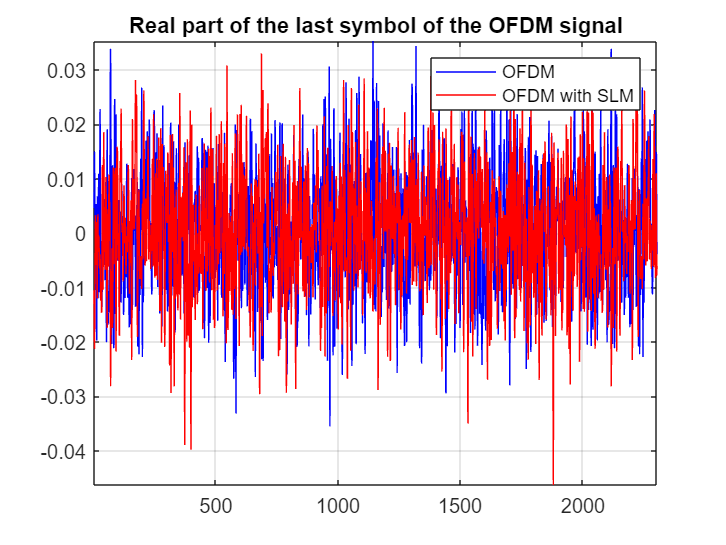

% Plot Real Part of the Last Symbol for Both Signals
figure;
plot(real(signal_original(end-2303:end)), 'b');
hold on
plot(real( signals(u, :)), 'r');
title('Real part of the last symbol of the OFDM signal');
legend('OFDM','OFDM with SLM')
grid on; 
axis tight;

We can also compare the spectrum between the original OFDM signal, and the signal with the PAPR reduction technique (SLM), seeing how they are exactly the same, since as we have explained before, this technique does not introduce any degradation to the signal, we are just reducing the PAPR value:

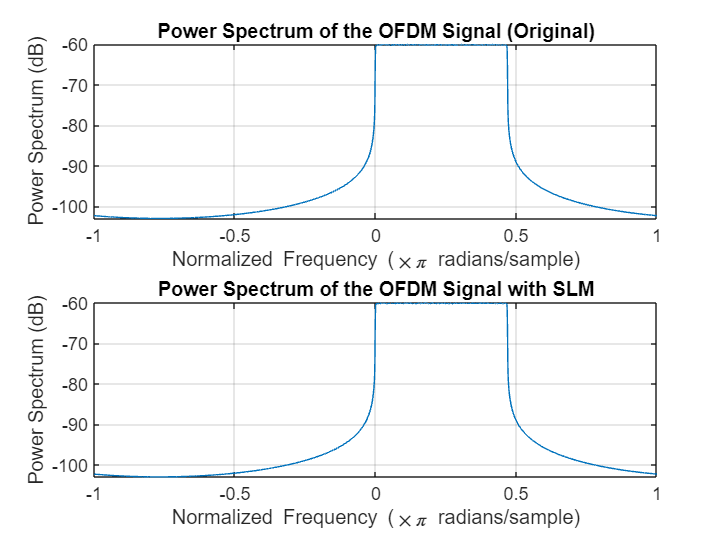

% Power Spectrum of the Original OFDM Signal
figure;
subplot(2,1,1)
pspectrum(signal_original);
title('Power Spectrum of the OFDM Signal (Original)');
subplot(2,1,2)
pspectrum(signal_slm);
title('Power Spectrum of the OFDM Signal with SLM');

Finally, with the SLM technique, is important to reflect the fact that as we increase the number of phase sequences we are trying*** U***, we get better results for the PAPR value, so the reduction is higher, for example, as we can see in the table below, we can get reductions of almost 2 dB using a number of phases of $2^{12}$. However, we must take into consideration that, as we increase the number of phases we want to try, the execution time also increases, therefore, we have a trade-off between the execution time and complexity (with a higher number of phases and a higher reduction of the PAPR value).

% Define values for FFT size, initial PAPR, and reduced PAPR
Number_phases = 2.^[12, 11, 10, 9, 8, 7, 6]';
initial_PAPR = 8.87 * ones(size(Number_phases));
reduced_PAPR = [6.92, 6.99, 7.06, 7.17, 7.24, 7.34, 7.46]';

% Calculate PAPR reduction
PAPR_reduction = initial_PAPR - reduced_PAPR;

% Create table
PAPR_Table = table(Number_phases, initial_PAPR, reduced_PAPR, PAPR_reduction, ...
                   'VariableNames', {'Number_phases', 'Initial_PAPR', 'Reduced_PAPR', 'PAPR_Reduction'});

% Display table
disp(PAPR_Table)

    Number_phases    Initial_PAPR    Reduced_PAPR    PAPR_Reduction
    _____________    ____________    ____________    ______________

        4096             8.87            6.92             1.95     
        2048             8.87            6.99             1.88     
        1024             8.87            7.06             1.81     
         512             8.87            7.17              1.7     
         256             8.87            7.24             1.63     
         128             8.87            7.34             1.53     
          64             8.87            7.46             1.41     



Finally, as we have exaplained before, since we have a random PAPR value for each symbol, we usually use the Cumulative Density Function (*cdf*) to represent the whole PAPR for all the signal:

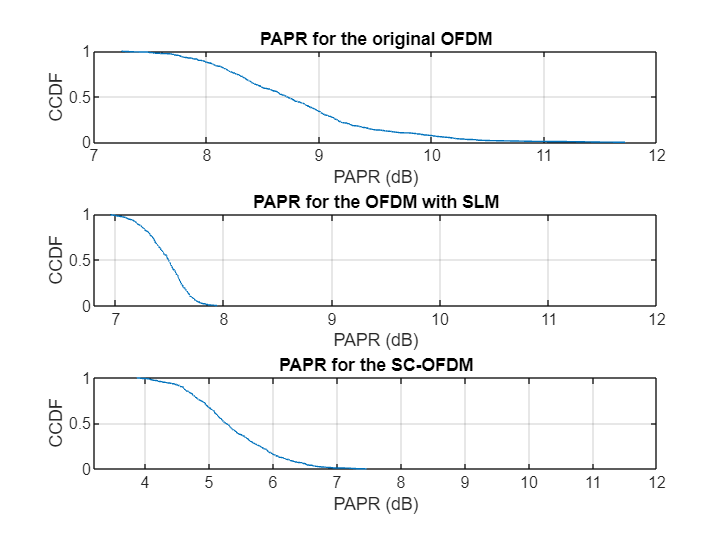

papr_ecdf=10 * log10(papr_original);
papr_ecdf_slm=10 * log10(papr_slm);
papr_ecdf_scfdma=10 * log10(papr_scfdma_low);
figure;
subplot(3,1,1)
[x,y]=ecdf(papr_ecdf);
plot(y,1-x)
grid
title('PAPR for the original OFDM')
xlabel('PAPR (dB)')
ylabel('CCDF')


subplot(3,1,2)
[x2,y2]=ecdf(papr_ecdf_slm);
plot(y2,1-x2)
grid
title('PAPR for the OFDM with SLM')
xlabel('PAPR (dB)')
ylabel('CCDF')
xlim([6.8 12])


subplot(3,1,3)
[x3,y3]=ecdf(papr_ecdf_scfdma);
plot(y3,1-x3)
grid
title('PAPR for the SC-OFDM')
xlabel('PAPR (dB)')
ylabel('CCDF')
xlim([3.2 12])

The **top plot **shows the CCDF of PAPR for a **standard OFDM** signal. In this plot, we observe that the PAPR values are relatively high, which is a known drawback of traditional OFDM. The CCDF curve starts high and gradually decreases as the PAPR (in dB) increases. This curve essentially indicates the probability of the PAPR exceeding a certain value, so a steeper decline is generally desirable to indicate lower PAPR values across the signal. Therefore, in the **middle plot**, the OFDM signal has been modified using a technique called** Selective Mapping** (SLM) to reduce PAPR. The curve shows a slight shift to the left compared to the original OFDM, indicating an overall reduction in PAPR. This means that SLM has succeeded in lowering the likelihood of high PAPR values, which can help improve power efficiency and reduce distortion in the transmitted signal. Finally, in the **bottom plot SC-OFDM** is used, which inherently has a lower PAPR compared to traditional OFDM. The CCDF curve starts lower and falls off more sharply, indicating that high PAPR values are even less likely. This makes SC-OFDM a suitable alternative for scenarios where minimizing PAPR is essential, such as in power-constrained devices.

Overall, these plots demonstrate how different methods and variations of OFDM (SLM and SC-OFDM) can effectively reduce PAPR compared to the original OFDM, as illustrated by the leftward shift in the CCDF curves.